# 5Mhz

T = 1/(2*5e6)

T = 1.0000e-07

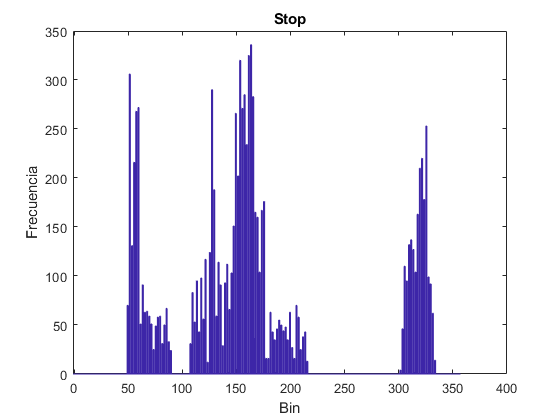

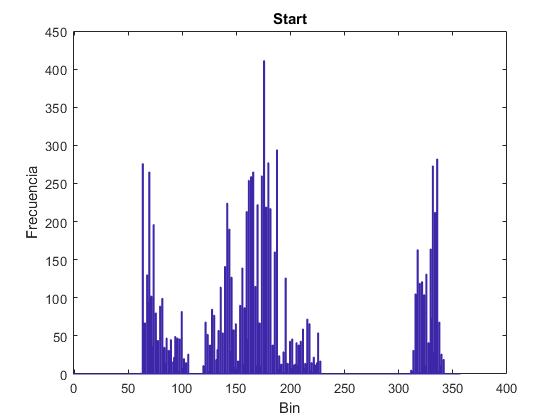

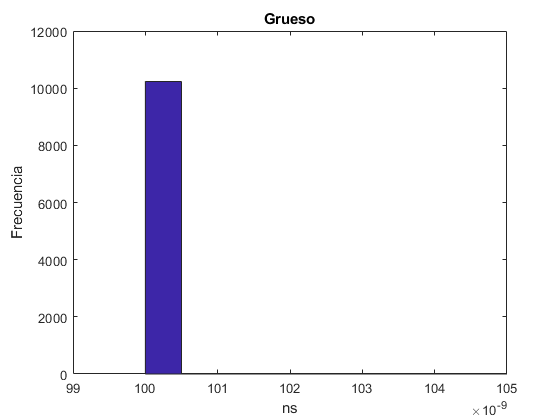

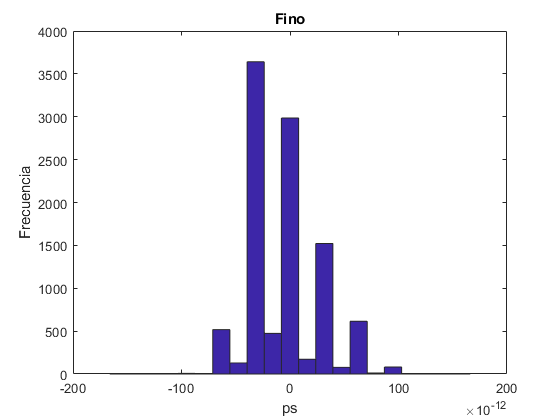

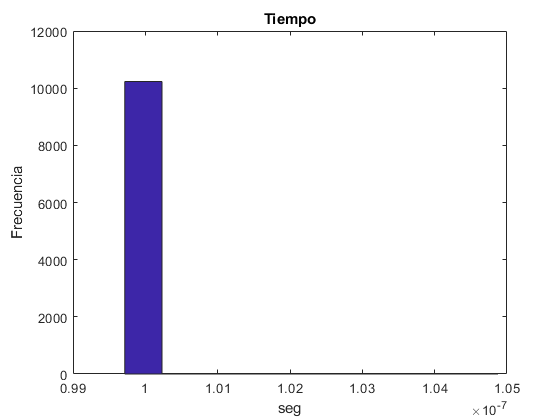

path5M = 'resultadosCSV_5mhz.txt'

data    = load(path5M);
stop    = data(:,1);
start   = data(:,2);
coarse  = data(:,3);
%%histograma de stop y start%%%%%%%%%%%%%%
bordes = -0.5:1:356.5;
figure;
hist(stop, bordes); title('Stop'); ylabel('Frecuencia'); xlabel('Bin');
figure;
hist(start, bordes); title('Start'); ylabel('Frecuencia'); xlabel('Bin');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tau_med = 15.82e-12;
T       = 1/(200e6);

t_grueso = coarse*T;
t_fino   = (stop-start)*tau_med;
t_medido = t_grueso + t_fino;

%%Grueso
figure;
hist(t_grueso); xlabel('ns'); ylabel('Frecuencia'); title('Grueso');
ax = gca;
ax.XAxis.Exponent = -9;

%%Fino
figure;
bordes_fino = tau_med*(-10:1:10);
hist(t_fino-mean(t_fino), bordes_fino); xlabel('ps'); ylabel('Frecuencia'); title('Fino');
ax = gca;
ax.XAxis.Exponent = -12;

figure;
clf;
%%Tiempo medido total
hist(t_medido); xlabel('seg'); ylabel('Frecuencia'); title('Tiempo');

# 500kHZ

T = 1/(2*500e3)

T = 1.0000e-06

path500k = 'resultadosCSV_500khz.txt'

path500k = 'resultadosCSV_500khz.txt'

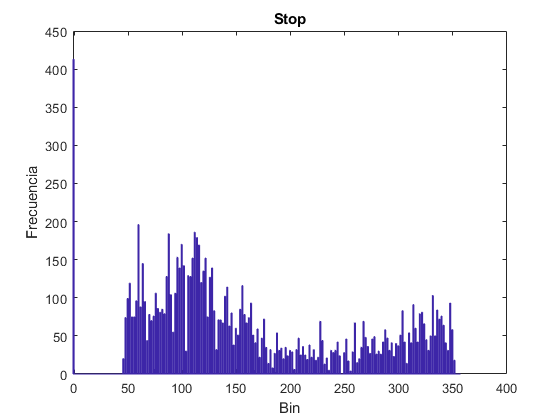

data    = load(path500k);
stop    = data(:,1);
start   = data(:,2);
coarse  = data(:,3);
%%histograma de stop y start%%%%%%%%%%%%%%
bordes = -0.5:1:356.5;
figure;
hist(stop, bordes); title('Stop'); ylabel('Frecuencia'); xlabel('Bin');

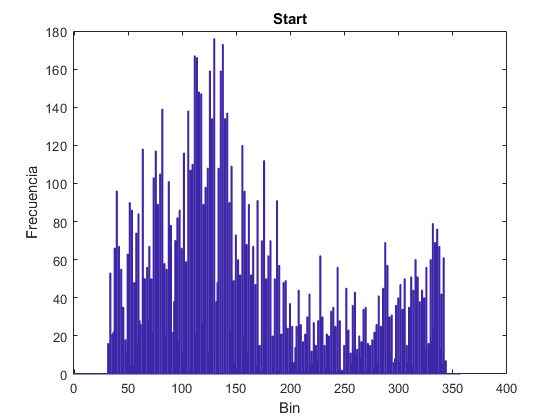

figure;
hist(start, bordes); title('Start'); ylabel('Frecuencia'); xlabel('Bin');

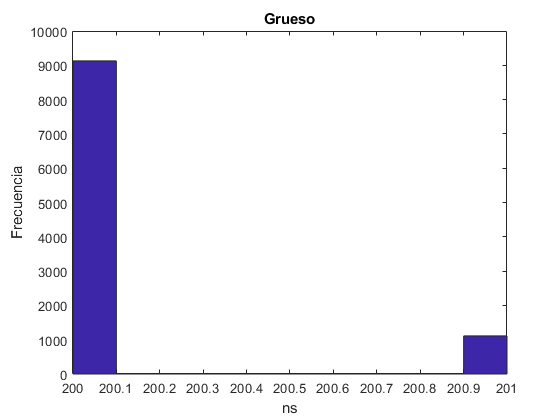


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tau_med = 15.82e-12;
T       = 1/(200e6);

t_grueso = coarse*T;
t_fino   = (stop-start)*tau_med;
t_medido = t_grueso + t_fino;

%%Grueso
figure;
hist(coarse); xlabel('ns'); ylabel('Frecuencia'); title('Grueso');

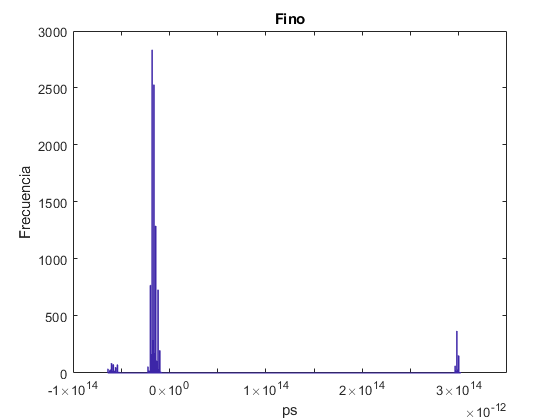


%%Fino
figure;
bordes_fino = tau_med*(-10:1:10);
hist(stop-start, 600); xlabel('ps'); ylabel('Frecuencia'); title('Fino');
% ax = gca;
% ax.XAxis.Exponent = -12;

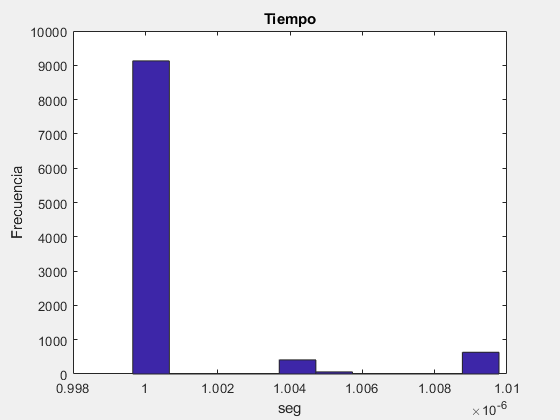


figure;
clf;
%%Tiempo medido total
hist(t_medido); xlabel('seg'); ylabel('Frecuencia'); title('Tiempo');